# Controller Design using Ragazzini's method

clear; clc; close all;
% Parameters
Ts = 1;     % sampling time
T = 10;     % time constent
ts = 10;    % settling time
zeta = 0.5; % damping ratio (overshoot 17%)

% System TF
num = 1;
den = conv ([1 0],[T 1]);
Gs = tf(num, den);

% Discrete System TF with zero-order-hold
% Can also use Gz = c2d (Gs, Ts, 'zoh')
A = T*(exp(-Ts/T) + (Ts/T) - 1);
B = T*(1-exp(-Ts/T)*(1 + Ts/T));
num_g =[0 A B];
dem_g =conv([1 -1], [1 -exp(-Ts/T)]);
Gz = tf(num_g, dem_g, Ts);

% Construct the desired closed-loop system TF
Tclp = ts/5;        % closed-loop system time constent
wn = 1/(Tclp*zeta); % natual frequency

num_r = wn^2;
den_r = [1 2*zeta*wn wn^2];
Hs = tf (num_r, den_r);


## First design

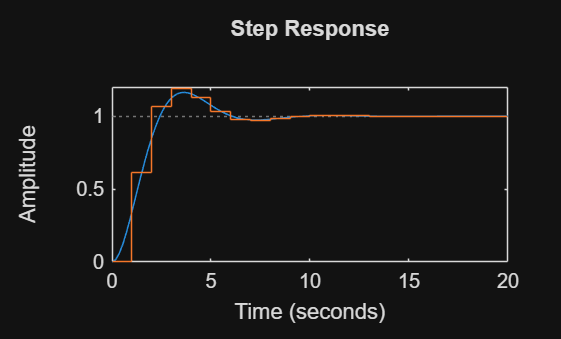

%Compute the discrete controller
r0 = exp(-wn*zeta*Ts);           % Pole radius
Omega0 = Ts*wn*sqrt(1-zeta^2);   % Pole angle
a = 0.4;    % select a small positive value alpha (<<1) to satisfy design constrains
% Calculate coeffecients
b2 = r0^2 - a;  
b1 = a + 1 - 2*r0*cos(Omega0);
num_c = conv([b1 b2], [1 -exp(-Ts/T)]);
dem_c = conv([A B], [1 -a]);

Cz = tf (num_c, dem_c, Ts);

% Plot the step response of the system with designed controller
Hz = feedback (Gz*Cz, 1);
figure (1)
step(Hs, Hz, 20);

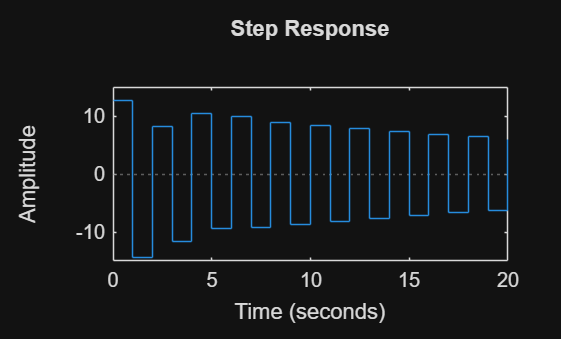

% Plot the controller behavior
Hz_p = feedback (Cz, Gz);
figure (2)
step (Hz_p, 20);

## Updated design

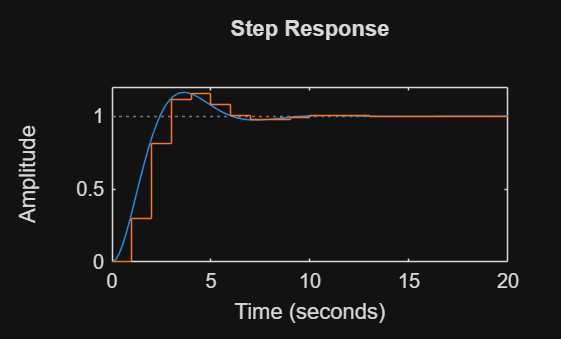

% Calculate parameters to conter the poles that close to -1
K = (1 - 2*r0*cos(Omega0) + r0^2)/(1 + B/A);
gamma = r0^2 - K*(B/A);
num_cn = (K/A)*[1 -exp(-Ts/T)];
dem_cn = [1 -gamma];
CNz = tf (num_cn, dem_cn, Ts);

% Plot the step response of the system with designed controller
HNz = feedback (Gz*CNz, 1);
figure (3)
step(Hs, HNz, 20);

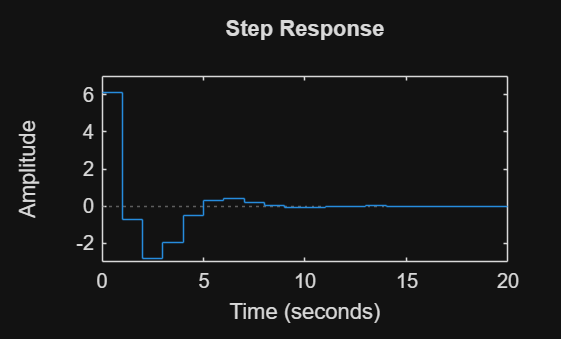

% Plot the controller behavior
HNz_p = feedback (CNz, Gz);
figure (4)
step (HNz_p, 20);